sympref('HeavisideAtOrigin', 1);

## Muestra la función de Transferencia H(s)

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                         2
3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=
X(s) - s X(s)

 
DESPEJAMOS Y(s)
 
Y(s)=
s + X(s) - s X(s) + 4
---------------------
      2
     s  + 3 s + 3

 
ANTES DE SUBSTITUIR LA TRANSFORMADA DE LA ENTRADA, FACTORIZAMOS PARA MOSTRAR LA FUNCION DE TRANSFERENCIA H(s)
 
H(s)

=
      s - 1
- ------------
   2
  s  + 3 s + 3

 
Aplicacmos transformada de Fourier a la función de transferencia, así su respuesta al impulso es
 
h(t)=
              /                               / sqrt(3) t \   \
              |                    sqrt(3) sin| --------- | 5 |
    /   3 t \ |    / sqrt(3) t \              \     2     /   |
-exp| - --- | | cos| --------- | - -------------------------- |
    \    2  / \    \     2     /                3             /

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                2
       s       s
s + ------ - ------ + 4
     2        2
    s  + 4   s  + 4
--------

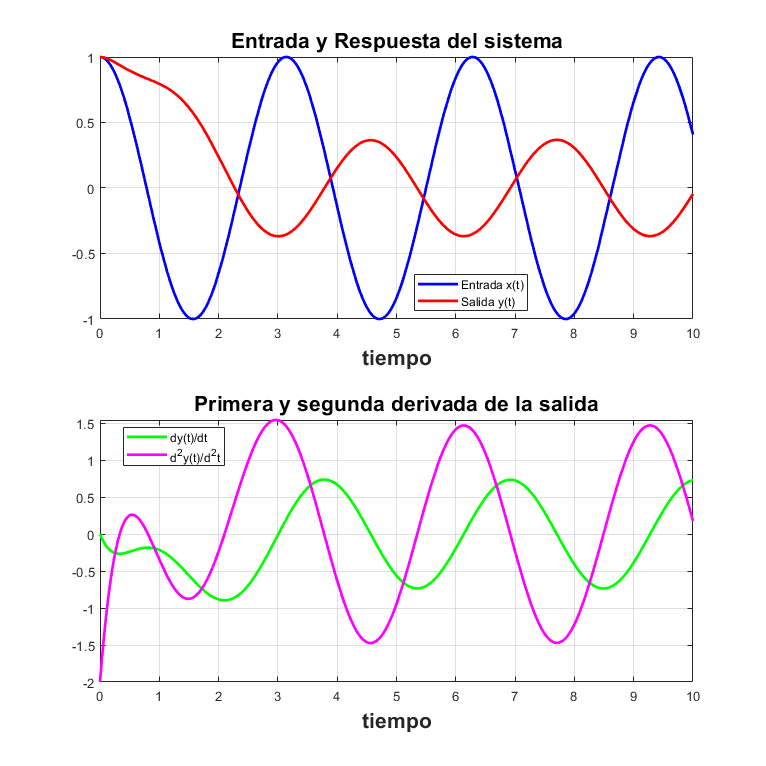

syms t
laplace2016a([3 3 1],[1,-1],[1,1],[0],cos(2*t)*heaviside(t),10)

function laplace2016a(a,b,ciy,cix,xi,t0)
% a coeficientes de las derivadas de la salida menor a mayor [a_0, ..., a_n]
% b coeficientes de las derivadas de la entrada menor a mayor [b_0, ..., b_m]
% ciy condiciones iniciales de la salida de  menor a mayor [y(0), y(0)^(n-1)]
% xi función de entrada en terminos de la variable simbolica t previamente
% declarada en el command window
% t0 tiempo final para graficar la solucion, la derivada, y la segunda 
% derivada 
% ejemplo: resolver y^(3)+y^(2)+2y^(1)+2y=3x^(2)-x^(1)+2x con y^(2)(0)=1 y^(1)=3
% y(0)=2, x(t)=exp(-t)cos(t)u(t), para 10 segundos, se resuleve como
% syms t
% laplace2016a([2 2 1 1],[2 -1 3],[2 3 1],exp(-t)*cos(t)*heaviside(t),10)
close all
tam=size(a);
tami=size(b);
syms y(t) Y(s) x(t) X(s) Yy fp H(s);
syms edd edi
%edy es la ecuacin diferencial dy sin condiciones iniciales
edy=0;
%edyc son las condiciones iniciales de dy
edyc=0;
%edxi es la ecuacin diferencial dx sin condiciones iniciales
edxi=0;
%edxci son las condiciones iniciales de dx
edxci=0;
%edh es la Transferencia
edh=0;

for i=1:tam(2)
   edy=edy+a(i)*s^(i-1)*Y(s);
   for k=1:i-1
       edyc=edyc-a(i)*(s^(i-1-k)*ciy(k));
   end
end

for i=1:tami(2)
   edxi=edxi+b(i)*s^(i-1)*X(s);
   for k=1:i-1
       edxci=edxci-b(i)*(s^(i-1-k)*cix(k));
   end
end
mensaje('APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales')

pretty(edy + edyc)
disp('=')
pretty(edxi + edxci)

mensaje('DESPEJAMOS Y(s)')

eddp=collect(edy + edyc,Y(s));
eddp=subs(eddp,Y(s),Yy);
eq1=eddp==edxi+edxci;
disp('Y(s)=')
eddp=solve(eq1, Yy);
pretty(simplify(eddp))

mensaje('ANTES DE SUBSTITUIR LA TRANSFORMADA DE LA ENTRADA, FACTORIZAMOS PARA MOSTRAR LA FUNCION DE TRANSFERENCIA H(s)')
edy = collect(edy,Y(s));
edy = edxi/edy;
edh = collect(edy, X(s));
edh = subs(edh, X(s), 1);
edh = subs(edh, Y(s), 1);

pretty(H(s));
disp('=');
pretty(edh);

mensaje('Aplicacmos transformada de Fourier a la función de transferencia, así su respuesta al impulso es')

disp('h(t)=');
pretty(simplify(ilaplace(edh)))


mensaje('SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA')

eddp=subs(eddp,X(s), laplace(xi));
pretty(eddp)
disp('=')
pretty(eddp)

%%% Para versiones superiores a 2016
mensaje('DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)')
disp('Y(s)=')
pretty(partfrac(eddp))
%%%% Si se ejecuta en 2015 o menor comentar las 3 lineas anteriores

mensaje('Aplicamos transformada inversa, asi la solución es')
disp('y(t)=')
y(t)=ilaplace(eddp);
pretty(y(t))

dy(t)=diff(y,t);
ddy(t)=diff(dy,t);
figure (1)
hFig = figure(1);
set(hFig, 'Position', [0 0 900 900])
axes1 = axes('Parent',hFig,'FontWeight','bold','FontSize',16);
tiempo=0:0.01:t0;
subplot(2,1,1)
fplot(xi,[0, t0],'b','LineWidth',2)

hold on
fplot(y,[0,t0],'r','LineWidth',2)

legend('Entrada x(t)','Salida y(t)','Location','Best')
xlabel('tiempo','FontWeight','bold','FontSize',16)
title('Entrada y Respuesta del sistema','FontWeight','bold','FontSize',16)
grid on
subplot(2,1,2)
fplot(dy,[0,t0],'g','LineWidth',2)

hold on
title('Primera y segunda derivada de la salida','FontWeight','bold','FontSize',16)
fplot(ddy,[0,t0],'m','LineWidth',2)

legend('dy(t)/dt','d^2y(t)/d^2t','Location','Best')
xlabel('tiempo','FontWeight','bold','FontSize',16)
grid on

end

function mensaje(texto)
disp( ' ')
disp(texto)
disp( ' ')
end

function fourier2016a(a,b,xi,t0)
% a coeficientes de las derivadas de la salida menor a mayor [a_0, ..., a_n]
% b coeficientes de las derivadas de la entrada menor a mayor [b_0, ..., b_m]
% xi función de entrada en terminos de la variable simbolica t previamente
% declarada en el command window
% t0 tiempo final para graficar la solucion, la derivada, y la segunda 
% derivada 
% ejemplo: resolver y^(2)+2y^(1)+2y=x^(1)+2x con y^(1)(0)=0
% y(0)=0, x(0)=0, x(t)=exp(-t)u(t), para 5 segundos, se resuleve como
% syms t
% fourier2016a([2 2 1],[2 1],exp(-t)*heaviside(t),5)
close all
tam=size(a);
tami=size(b);
syms y(t) Y(w) x(t) X(w) Yy fp;
syms edd edi 
edd=0;
edi=0;

for i=1:tam(2)
   edd=edd+a(i)*(j*w)^(i-1)*Y(w);
end

for i=1:tami(2)
   edi=edi+b(i)*(j*w)^(i-1)*X(w);  
end
mensaje('APLICAMOS TRANSFORMADA DE FOURIER')

pretty(edd)
disp('=')
pretty(edi)

mensaje('SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA')

edi=subs(edi,X(w), fourier(xi));
pretty(edd)
disp('=')
pretty(edi)

mensaje('DESPEJAMOS Y(w)')

edd=collect(edd,Y(w));
edd=subs(edd,Y(w),Yy);
eq1=edd==edi;
disp('Y(w)=')
edd=solve(eq1, Yy);
pretty(edd)

%%% Para versiones superiores a 2016
mensaje('DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(w)')
disp('Y(w)=')
pretty(partfrac(edd))
%%%% Si se ejecuta en 2015 o menor comentar las 3 lineas anteriores
 
mensaje('Aplicamos transformada inversa, asi la solución es')
disp('y(t)=')
y(t)=ifourier(edd,t);
pretty(y(t))

figure (1)
hFig = figure(1);
set(hFig, 'Position', [0 0 900 900])
axes1 = axes('Parent',hFig,'FontWeight','bold','FontSize',16);
tiempo=0:0.01:t0;
fplot(xi,[0, t0],'b','LineWidth',2)
hold on
fplot(y,[0,t0],'r','LineWidth',2)
legend('Entrada x(t)','Salida y(t)','Location','Best')
xlabel('tiempo','FontWeight','bold','FontSize',16)
title('Entrada y Respuesta del sistema','FontWeight','bold','FontSize',16)
grid on
end